# In the Name of God

close all;
clearvars;
clear;
clc;

## Exc) 3-1

map_set = create_mape_set();

## Exc) 3-2

bit_rate = 1;
msg = 'bc';
[signal, t] = coding_amp(msg, bit_rate, map_set);

0000100010


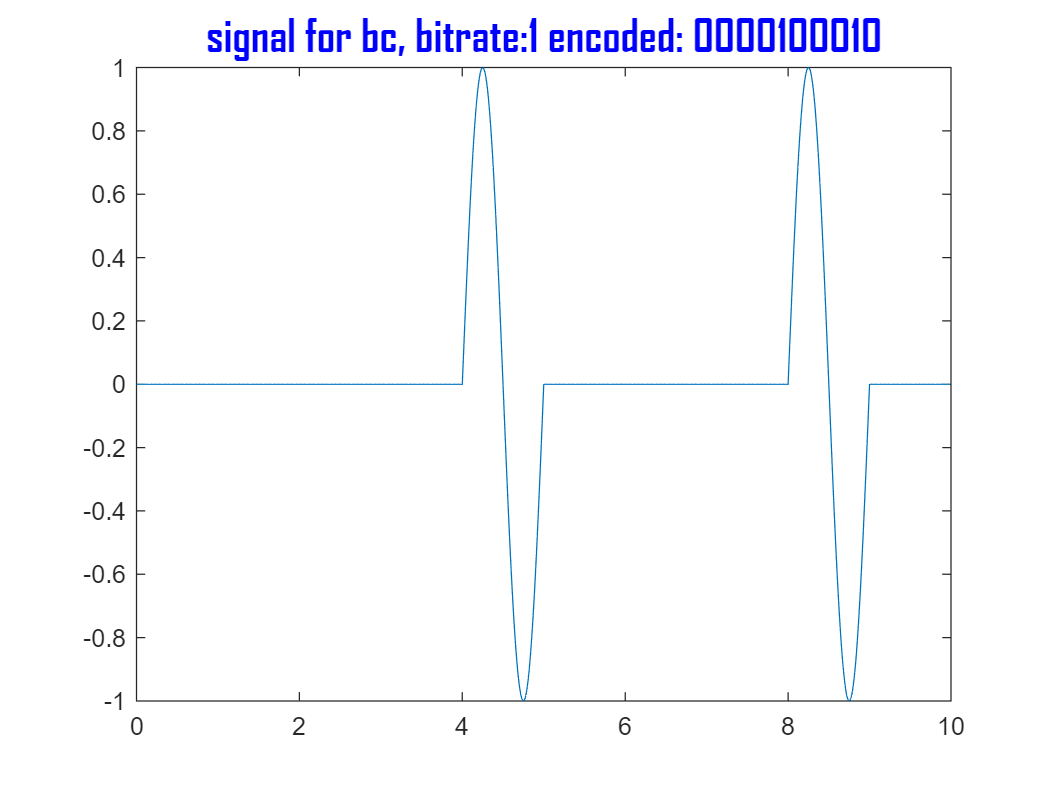

figure('Name', '3-2');
plot(t, signal);
title('signal for bc, bitrate:1 encoded: 0000100010', 'FontSize', 18, 'Color', 'b', 'FontName', 'Agency FB');

## Exc) 3-3

msg = 'signal';

bit_rate = 1;
[signal1, t1] = coding_amp(msg, bit_rate, map_set);

100100100000110011010000001011


bit_rate = 2;
[signal2, t2] = coding_amp(msg, bit_rate, map_set);

100100100000110011010000001011


bit_rate = 3;
[signal3, t3] = coding_amp(msg, bit_rate, map_set);

100100100000110011010000001011


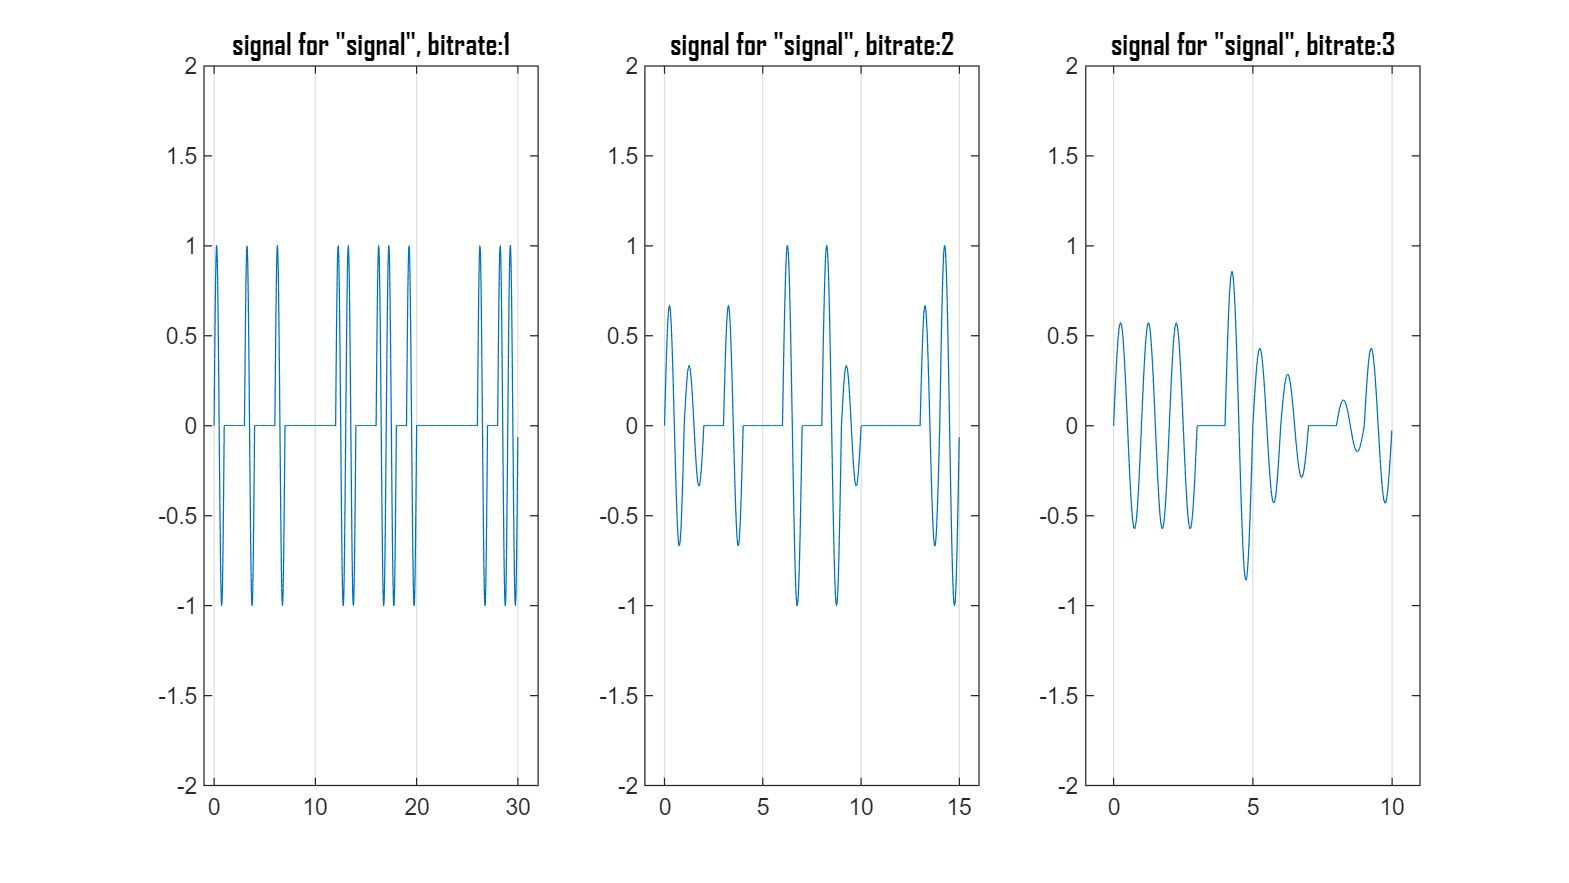

figure('units','normalized','outerposition',[0 0 1 1], 'Name', '3-3')

subplot(1,3,1);
plot(t1, signal1);
title('signal for "signal", bitrate:1', 'FontSize', 12, 'FontName', 'Agency FB');

subplot(1,3,2);
plot(t2, signal2);
title('signal for "signal", bitrate:2', 'FontSize', 12, 'FontName', 'Agency FB');

subplot(1,3,3);
plot(t3, signal3);
title('signal for "signal", bitrate:3', 'FontSize', 12, 'FontName', 'Agency FB');

subplot(1,3,1)
xlim([-1 32.0])
ylim([-2.00 2.00])
set(gca,'XGrid','on','YGrid','off')

subplot(1,3,2)
xlim([-1 16.0])
ylim([-2.00 2.00])
set(gca,'XGrid','on','YGrid','off')

subplot(1,3,3)
xlim([-1 11.0])
ylim([-2.00 2.00])
set(gca,'XGrid','on','YGrid','off')

## Exc) 3-4

r1 = decoding_amp(signal1, t1, 1, map_set)

100100100000110011010000001011


r1 = "signal"

r2 = decoding_amp(signal2, t2, 2, map_set)

100100100000110011010000001011


r2 = "signal"

r3 = decoding_amp(signal3, t3, 3, map_set)

100100100000110011010000001011


r3 = "signal"

disp(r1)

signal


disp(r2)

signal


disp(r3)

signal


% CORRECT OUTPUT:
% 100100100000110011010000001011

## Exc) 3-5

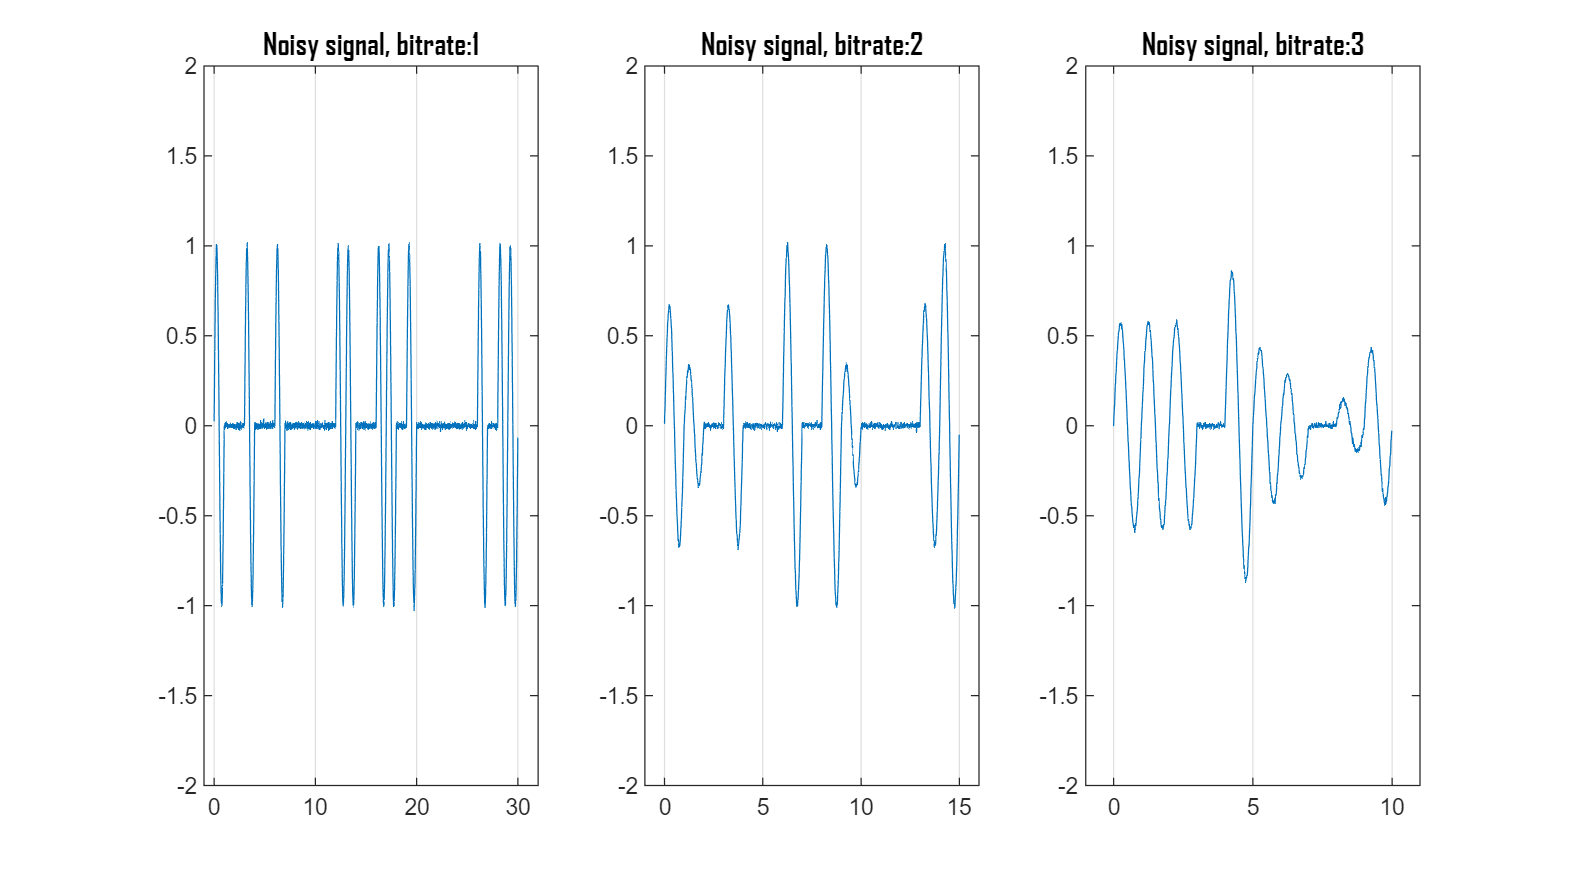

100100100000110011010000001011
100100100000110011010000001011
100100100000110011010000001011
signal
signal
signal
bitRate1 CORRECT
bitRate2 CORRECT
bitRate3 CORRECT


alpha = 0.01;
evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg);

## Exc) 3-6.3-7

As you can see in output:

alpha = 0.1 -> ALL CORRECT

alpha = 0.2 -> bitrate 3 INCORRECT

alpha = 0.5 -> bitrate 3 INCORRECT

alpha = 0.7 -> bitrate 3&2 INCORRECT

alpha =2.5, 3.5 -> ALL INCORRECT

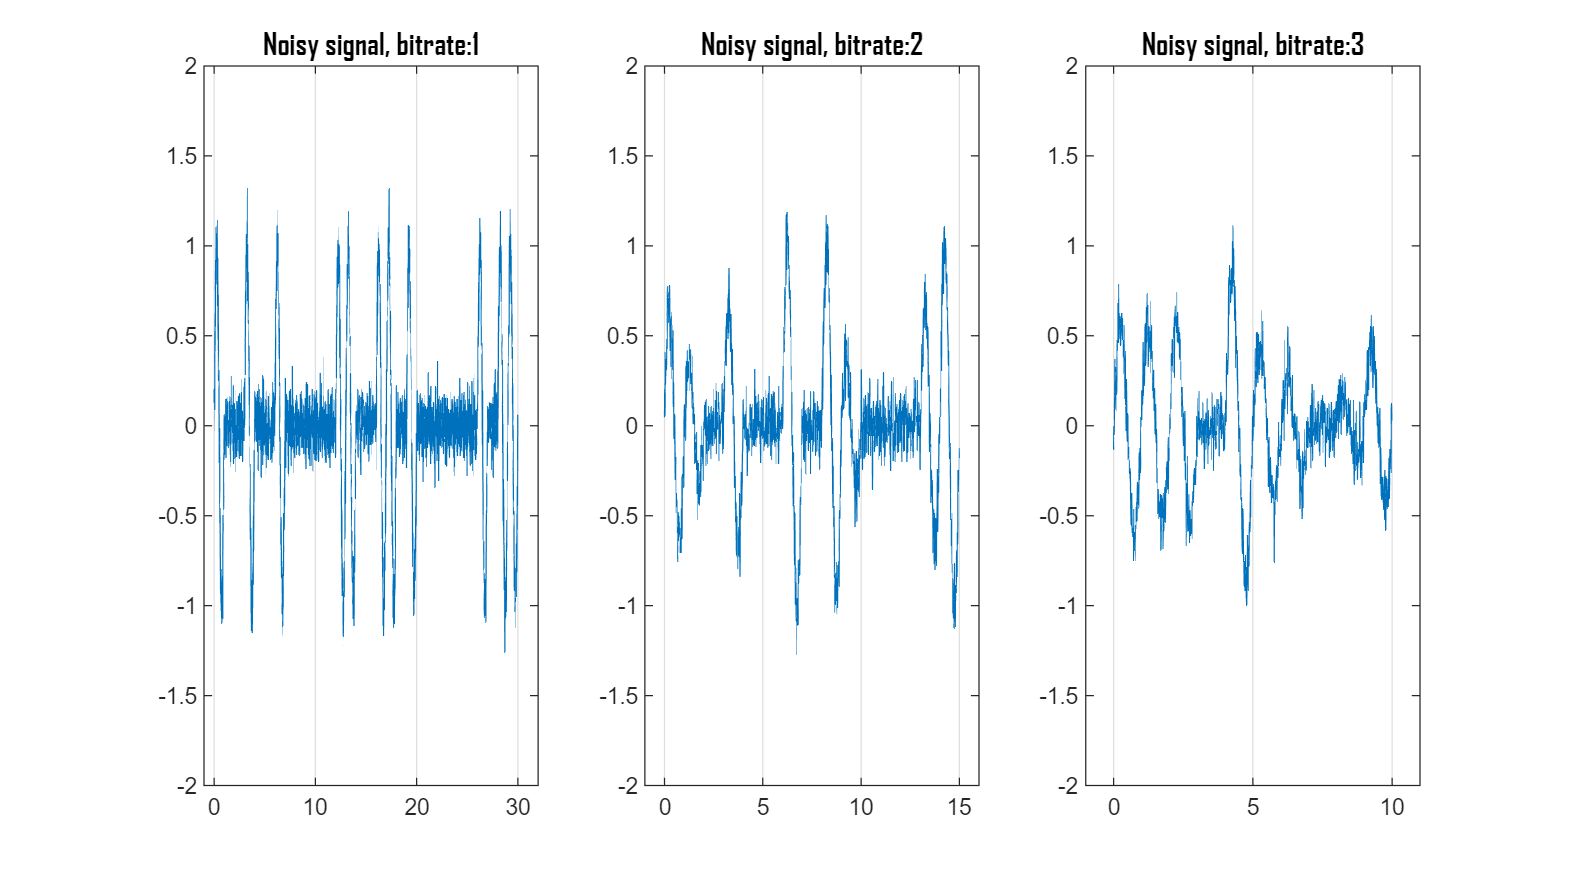

100100100000110011010000001011
100100100000110011010000001011
100100100000110011010000001011
signal
signal
signal
bitRate1 CORRECT
bitRate2 CORRECT
bitRate3 CORRECT


alpha = 0.1;
evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg);

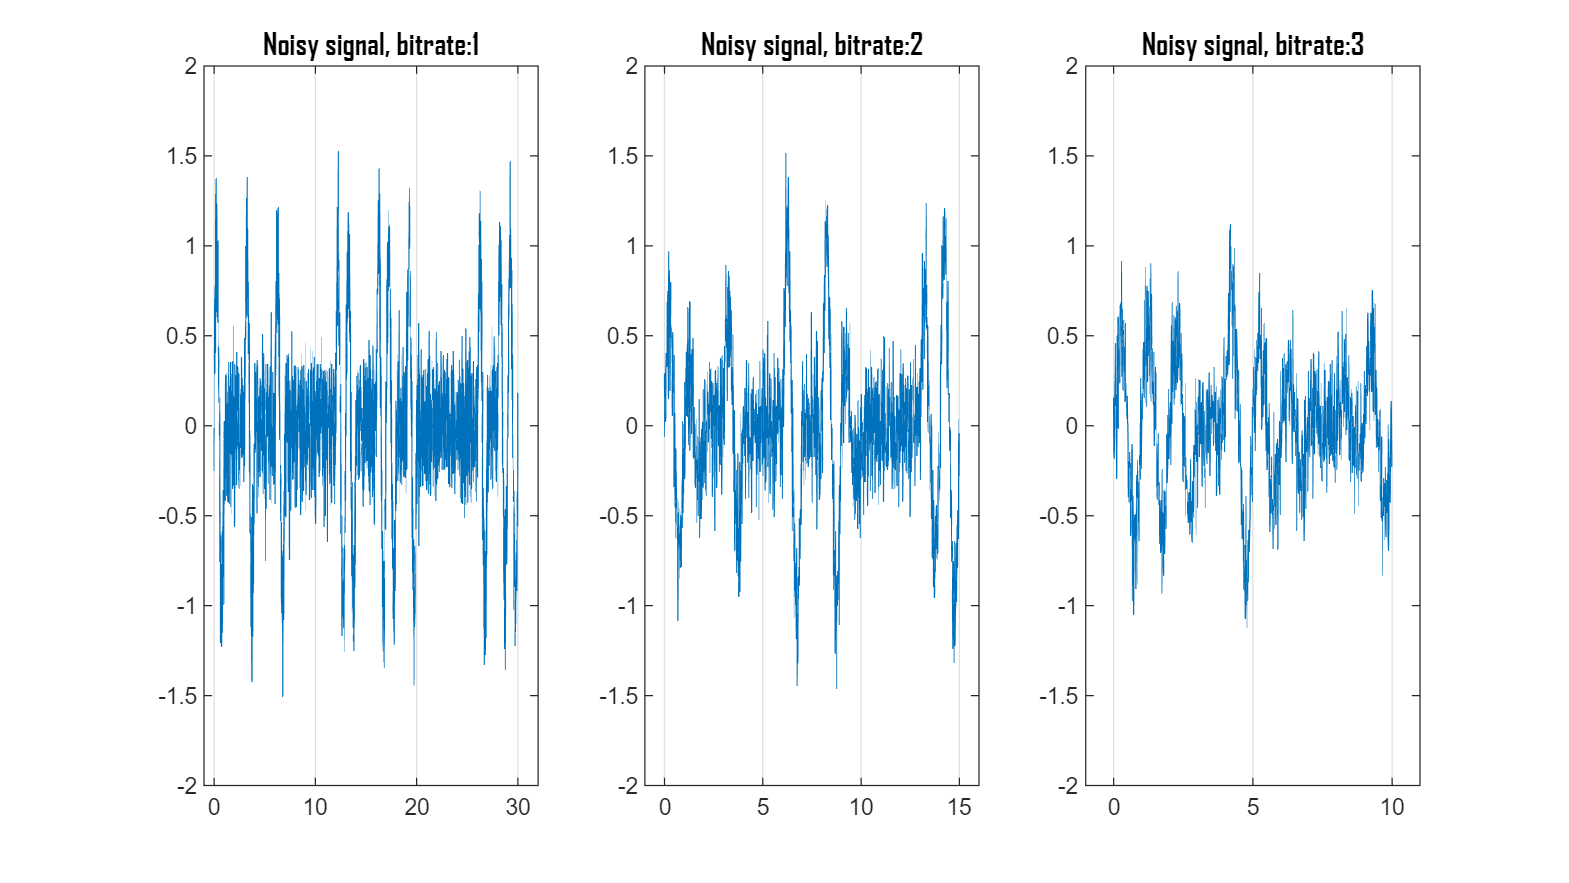

100100100000110011010000001011
100100100000110011010000001011
100100011000110011010000001011
signal
signal
sggnal
bitRate1 CORRECT
bitRate2 CORRECT
bitRate3 INCORRECT


alpha = 0.2;
evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg);

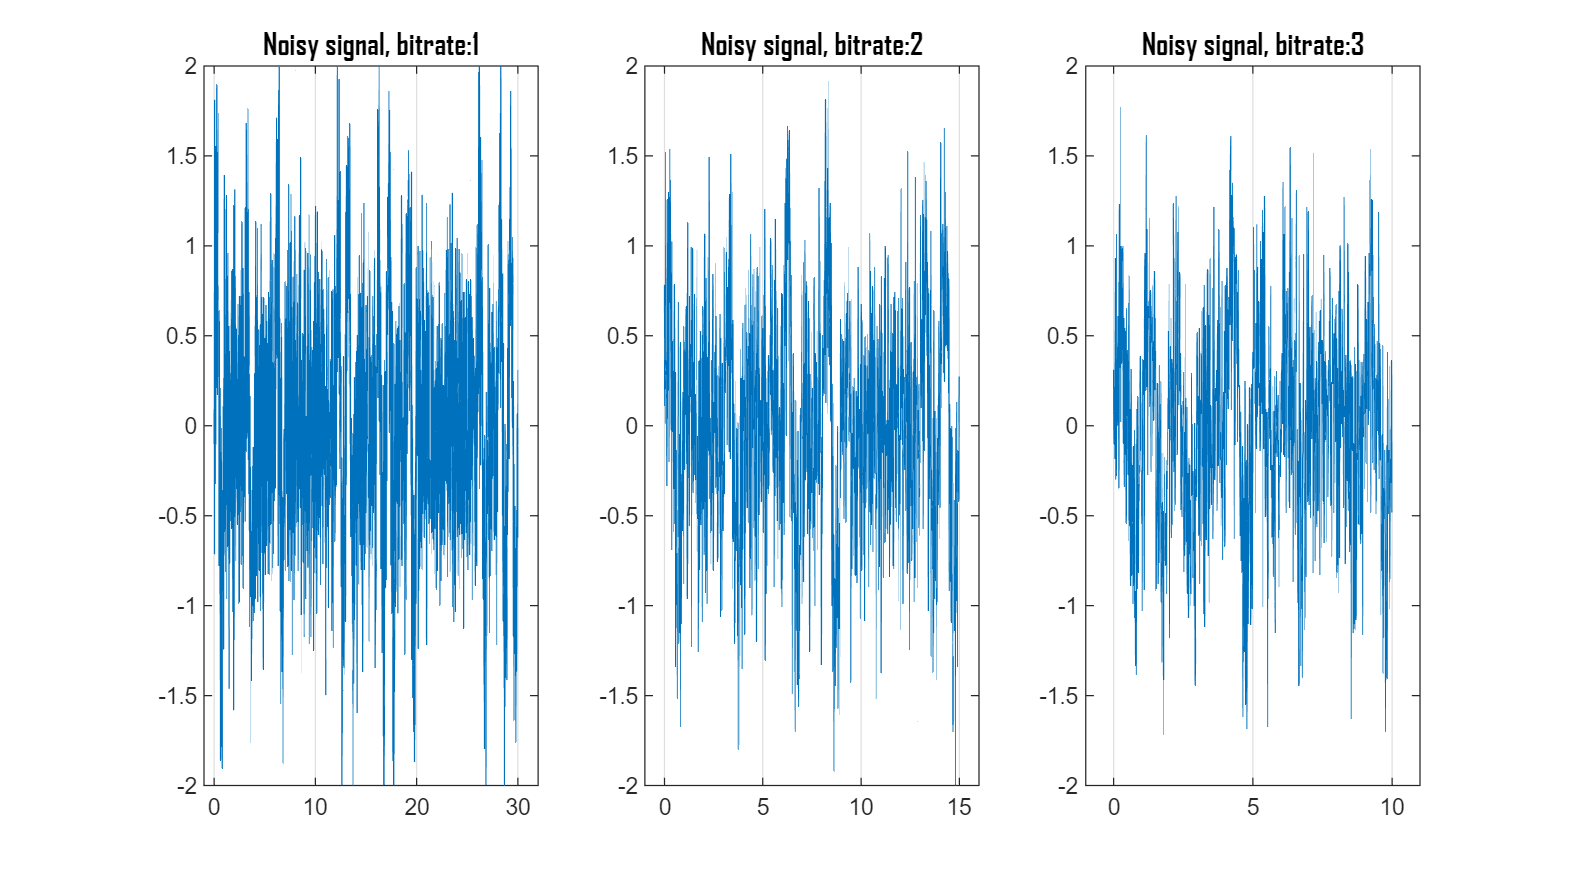

100100100000110011010000001011
100100100000110011010000001011
100100100000110010011000010100
signal
signal
sigjqu
bitRate1 CORRECT
bitRate2 CORRECT
bitRate3 INCORRECT


alpha = 0.5;
evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg);

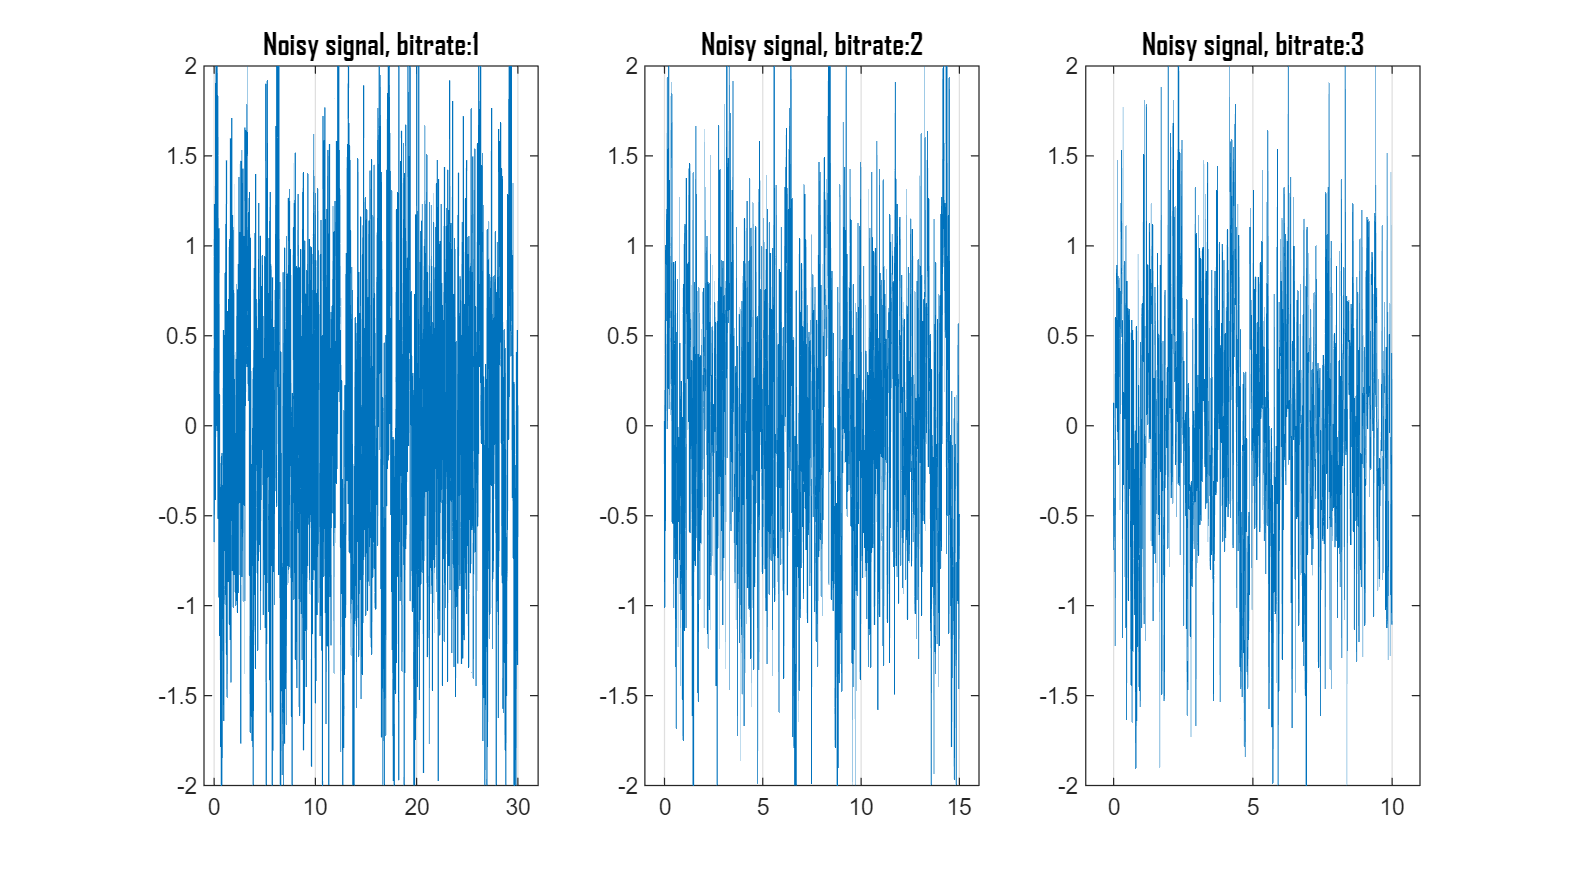

100100100000110011010000001011
100100100000100011010000001011
100010100001101011010000000010
signal
sienal
rinnac
bitRate1 CORRECT
bitRate2 INCORRECT
bitRate3 INCORRECT


alpha = 0.7;
evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg);

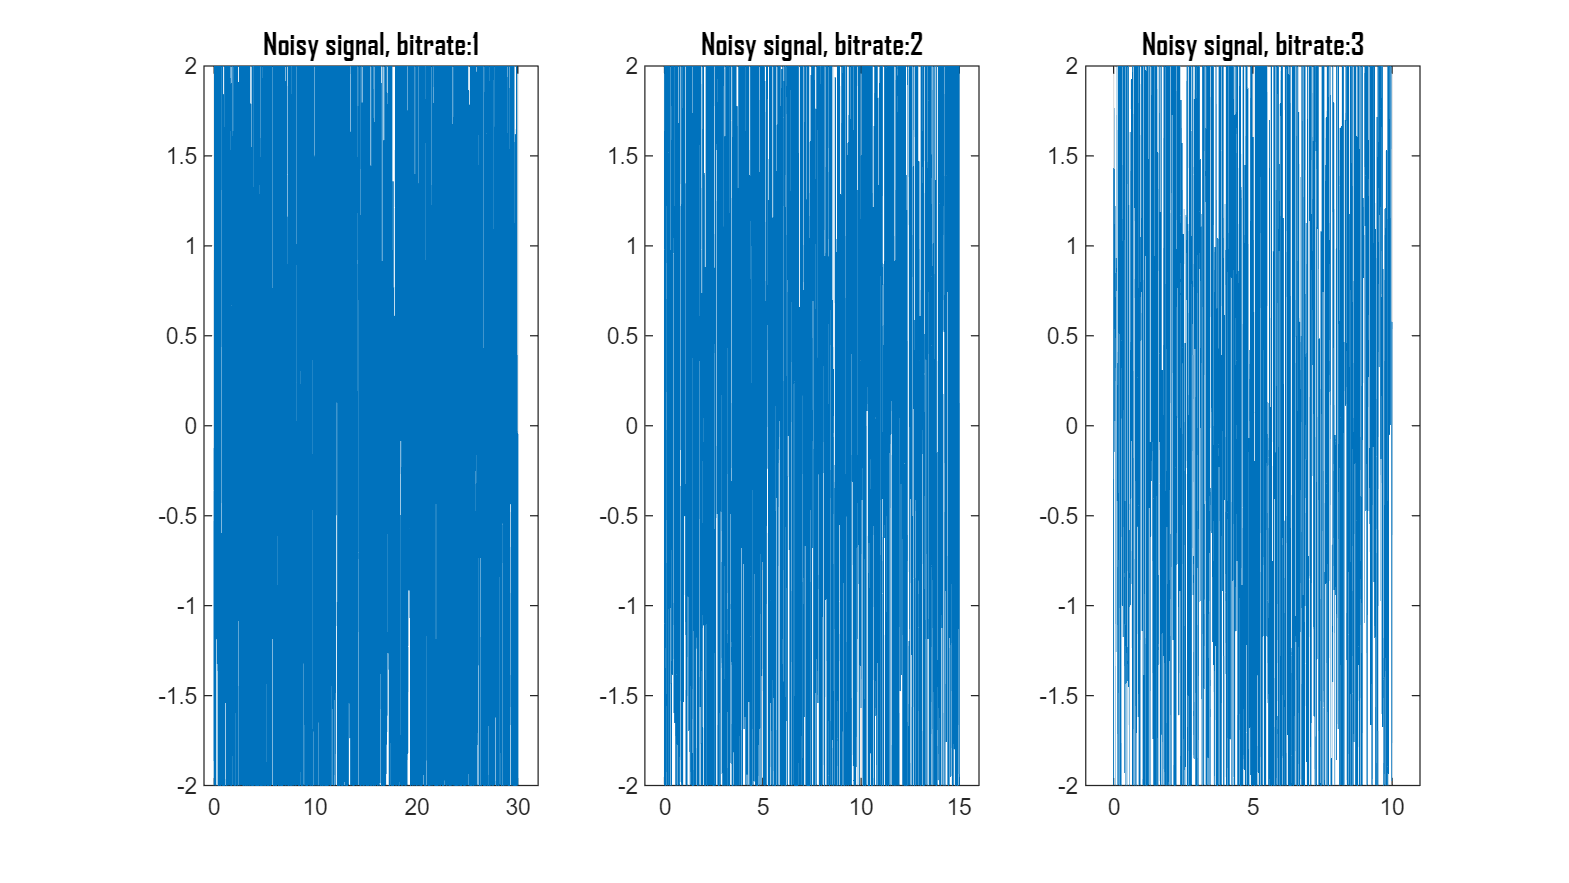

110100000000110011110000001011
010000000000100011000110001110
100010100001111111010010000100
 agpal
iaemmo
rip!ee
bitRate1 INCORRECT
bitRate2 INCORRECT
bitRate3 INCORRECT


alpha = 2.5;
evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg);

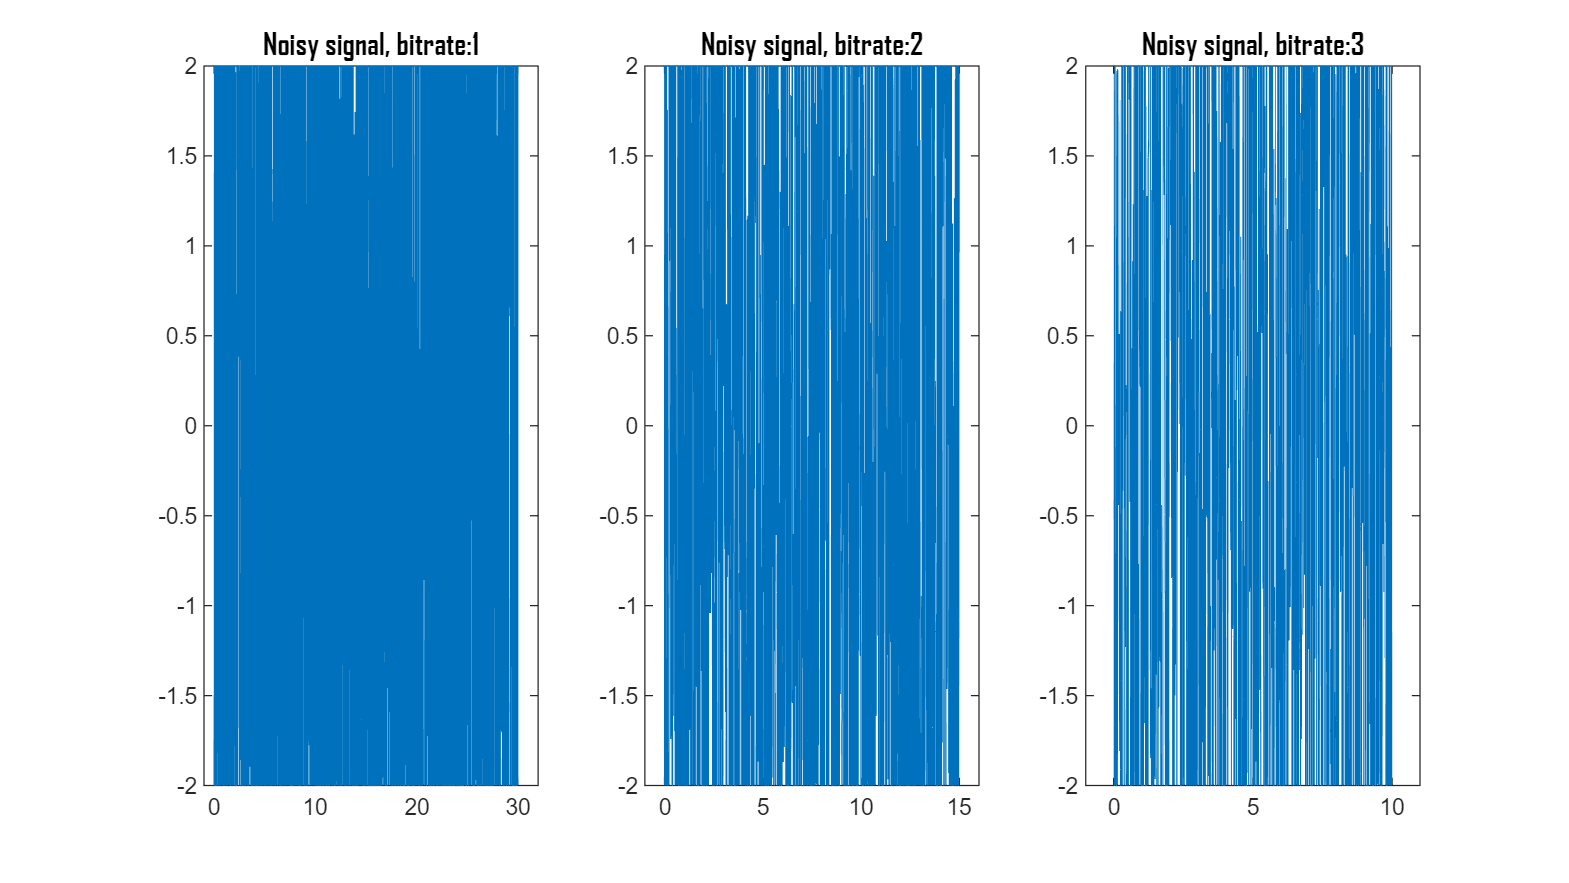

100001100001110011010000001011
010000010000000011000001001111
010010111000111100000000011100
qyonal
ieamcp
johqa,
bitRate1 INCORRECT
bitRate2 INCORRECT
bitRate3 INCORRECT


alpha = 3.5;
evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg);

## Functions:

function evaluate(signal1, t1, signal2, t2, signal3, t3, alpha, map_set, msg)
    noise1 = alpha * randn(1, length(signal1));
    noise2 = alpha * randn(1, length(signal2));
    noise3 = alpha * randn(1, length(signal3));
    
    noisy_signal1 = signal1 + noise1;
    noisy_signal2 = signal2 + noise2;
    noisy_signal3 = signal3 + noise3;

    figure('units','normalized','outerposition',[0 0 1 1], 'Name', '3-3')

    subplot(1,3,1);
    plot(t1, noisy_signal1);
    title('Noisy signal, bitrate:1', 'FontSize', 12, 'FontName', 'Agency FB');
    
    subplot(1,3,2);
    plot(t2, noisy_signal2);
    title('Noisy signal, bitrate:2', 'FontSize', 12, 'FontName', 'Agency FB');
    
    subplot(1,3,3);
    plot(t3, noisy_signal3);
    title('Noisy signal, bitrate:3', 'FontSize', 12, 'FontName', 'Agency FB');
    
    subplot(1,3,1)
    xlim([-1 32.0])
    ylim([-2.00 2.00])
    set(gca,'XGrid','on','YGrid','off')
    
    subplot(1,3,2)
    xlim([-1 16.0])
    ylim([-2.00 2.00])
    set(gca,'XGrid','on','YGrid','off')
    
    subplot(1,3,3)
    xlim([-1 11.0])
    ylim([-2.00 2.00])
    set(gca,'XGrid','on','YGrid','off')

    r1 = decoding_amp(noisy_signal1, t1, 1, map_set);
    r2 = decoding_amp(noisy_signal2, t2, 2, map_set);
    r3 = decoding_amp(noisy_signal3, t3, 3, map_set);

    disp(r1);
    disp(r2);
    disp(r3);

    if strcmp(r1, msg)
        disp("bitRate1 CORRECT");
    else
        disp("bitRate1 INCORRECT");
    end

    if strcmp(r2, msg)
        disp("bitRate2 CORRECT");
    else
        disp("bitRate2 INCORRECT");
    end

    if strcmp(r3, msg)
        disp("bitRate3 CORRECT");
    else
        disp("bitRate3 INCORRECT");
    end

end

function bin_representation = find_nearest(bit_rate, corr_res)
    max = 2 ^ bit_rate - 1;
    min_diff = 1000;
    best_guess = 1;
    for i = 0:max
        diff = abs(corr_res - i/max);
        if diff < min_diff
            min_diff = diff;
            best_guess = i;
        end
    end
    bin_representation = dec2bin(best_guess, bit_rate);
end

function output = decoding_amp(signal, tt, bit_rate, map_set)
    time = length(tt)/100;
    t_start = 0;
    t_end = 1;
    fs = 100;
    ts = 1/fs;
    t = t_start:ts:t_end-ts;
    corr_func = 2*sin(2*pi*t);
    coded_signal = '';
    for i = 1 : time
        s = signal((i-1)*100 + 1 : i*100);
        m = 0;
        for j = 1:100
            m = m + s(j)*corr_func(j);
        end
        coded_signal = [coded_signal, find_nearest(bit_rate, m / 100)];
    end
    output = "";
    disp(coded_signal);
    for i = 1 : length(coded_signal) / 5
        bin = coded_signal((i-1)*5+1:i*5);
        for j = 1:32
            if(strcmp(map_set(2,j), bin))
                output = output + map_set(1,j);
                break;
            end
        end
    end
end

function [signal, t_totall] = coding_amp(msg, bit_rate, map_set)
max = 2 ^ bit_rate - 1;

coded_signal = "";
for i = 1 : length(msg)
    for j = 1 : 32
        if strcmp( msg(i), map_set(1, j))
            coded_signal = coded_signal + map_set(2, j);
            break
        end
    end
end

while rem(strlength(coded_signal), bit_rate) ~= 0
    coded_signal = coded_signal + '0';
end

coded_signal = convertStringsToChars(coded_signal);

t_start = 0;
t_end = 1;
fs = 100;
ts = 1/fs;
t = t_start:ts:t_end-ts;

t_final = length(coded_signal) / bit_rate;

t_totall = 0:ts:t_final-ts;
signal = [];
for i = 1 : length(coded_signal) / bit_rate
    t = t_start:ts:t_end-ts;
    t_start = t_start + 1;
    t_end = t_end + 1;
    val = bin2dec(coded_signal((i - 1)*bit_rate+1 :i*bit_rate));
    s = val * sin(2 * pi * t) / max;
    signal = [signal , s];
end
disp(coded_signal);

end

function map_set = create_mape_set()
map_set = cell(2, 32);

i = 1;
for letter = 'a' : 'z'
    map_set{1, i} = letter;
    map_set{2, i} = dec2bin(i - 1, 5);
    i = i + 1;
end

map_set{1, 27} = ' ';
map_set{1, 28} = '.';
map_set{1, 29} = ',';
map_set{1, 30} = '!';
map_set{1, 31} = ';';
map_set{1, 32} = '"';

map_set{2, 27} = '11010';
map_set{2, 28} = '11011';
map_set{2, 29} = '11100';
map_set{2, 30} = '11101';
map_set{2, 31} = '11110';
map_set{2, 32} = '11111';
end